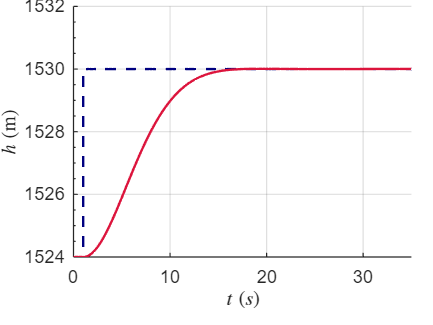

clear
clc


% 0 Controller value

Kp_1 = -99.9;

Kp_2 = -65;

Ki_2 = 0.11;

Kp_3 = -0.033;

Ki_3 = -0.00001;

Kp_4 = -0.0025;

Ki_4 = -0.0027;

Kp_5 = -0.17;

Ki_5 = -0.000017;

% 1 Run model
open('Altitude_Hold.slx')
out = sim('Altitude_Hold.slx');

% 2 Extract time and signal data
t = out.h.Time;
h = out.h.Data;
step = out.step.Data;

% 3 Compute step response characteristics

% Plot for verification
[ha, pos] = tight_subplot(1,1, ...   % Nh, Nw
                          [0.08 0.08], ...
                          [0.21 0.02], ...    % marg_h [bottom top]
                          [0.17 0.05]);       % marg_w [left  right]

ax = ha(1);            % handle to the only axes
axes(ax);              % activate it

plot(t, step, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on
plot(t, h, 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 35]);
ylim([1524 1532]);

xlabel('$t \; (s)$', 'Interpreter', 'latex');
ylabel('$h \; (\mathrm{m})$', 'Interpreter', 'latex');


grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 400 300]);


% Compute step response characteristics
info = stepinfo(h-1524, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 8.2554
    TransientTime: 14.3901
     SettlingTime: 14.3901
      SettlingMin: 5.4696
      SettlingMax: 6.0083
        Overshoot: 0.0793
       Undershoot: 0
             Peak: 6.0083
         PeakTime: 19.2335

